### Circuito Linea de Tranmision

clear all
Start_Freq=0.1E9;
End_Freq=2.5E9;
Step=1000;
Z0=50;

netlist_TLfile='NetlistSpice\ElementosSerie.net';
netlistCell=Netlist2CellArray(netlist_TLfile)

netlistCell = 3×7 cell array
    {'SSC1'}    {'N001'}    {'N003'}    {'SSC'}    {[        45]}    {[45]}    {[1.0000e+09]}
    {'L1'  }    {'N003'}    {'N004'}    {'L'  }    {[1.0000e-08]}    {[ 0]}    {[         0]}
    {'R1'  }    {'N004'}    {'N002'}    {'R'  }    {[        75]}    {[ 0]}    {[         0]}



% Metodo Objeto Circuito Matlab
freq=linspace(Start_Freq, End_Freq, Step);
SMatlab4=SParametersFromNetlist(netlistCell,Start_Freq,End_Freq,Step,Z0);

Stub =   txlineElectricalLength: ElectricalLength element

                  Name: 'StubCorto'
                    Z0: 45
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Short'
              StubMode: 'Series'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}
           ParentNodes: [1 3 0 0]
            ParentPath: 'unnamed'


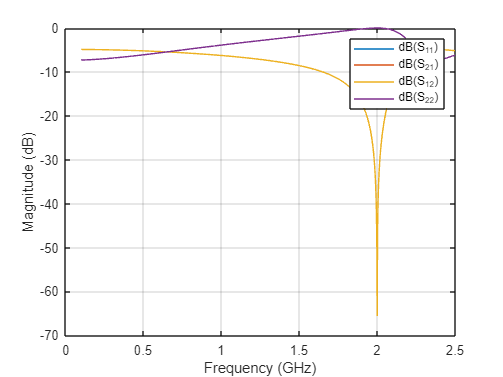


% ZMatlab=s2z(SMatlab4.Parameters,50);
% ZMatlab=zparameters(ZMatlab,freq);
% param = rfparam(ZMatlab,1,1);
% plot(freq,real(param));

rfplot(SMatlab4);




% Metodo circuito equivalente
nuevo_Netlist=NetlistCircuitoEquivalente(netlistCell)

nuevo_Netlist = 1×7 cell array
    {'Series'}    {'N001'}    {'N002'}    {'R,L,SSC,'}    {[75 1.0000e-08 45]}    {[0 0 45]}    {[0 0 1.0000e+09]}


% Matriz_Z=Z_parameters(nuevo_Netlist, Start_Freq, End_Freq, Step, 2);
% Matriz_S=z2s(Matriz_Z,50);

Matriz_Y=Y_parameters(nuevo_Netlist, Start_Freq, End_Freq, Step, 2);
Matriz_S=y2s(Matriz_Y,Z0);


freq=linspace(Start_Freq, End_Freq, Step);
SParamsObject=sparameters(Matriz_S,freq,50);
rfplot(SParamsObject)


% ----- INICIO----------


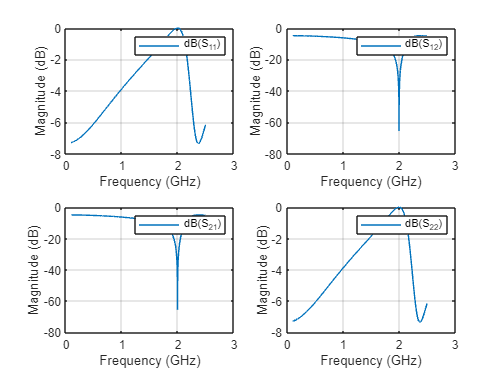

subplot(2,2,1)
rfplot(SMatlab4,1,1)
subplot(2,2,2)
rfplot(SMatlab4,1,2)
subplot(2,2,3)
rfplot(SMatlab4,2,1)
subplot(2,2,4)
rfplot(SMatlab4,2,2)



% subplot(2,2,1)
% smithplot(SMatlab4,1,1)
% subplot(2,2,2)
% smithplot(SMatlab4,1,2)
% subplot(2,2,3)
% smithplot(SMatlab4,2,1)
% subplot(2,2,4)
% smithplot(SMatlab4,2,2)

% subplot(2,2,1)
% rfplot(SMatlab4,1,1,'imag')
% subplot(2,2,2)
% rfplot(SMatlab4,1,2,'imag')
% subplot(2,2,3)
% rfplot(SMatlab4,2,1,'imag')
% subplot(2,2,4)
% rfplot(SMatlab4,2,2,'imag')

% subplot(2,2,1)
% param = rfparam(ZMatlab,1,1);
% plot(freq,real(param));
% subplot(2,2,2)
% param = rfparam(ZMatlab,1,2);
% plot(freq,real(param));
% subplot(2,2,3)
% param = rfparam(ZMatlab,2,1);
% plot(freq,real(param));
% subplot(2,2,4)
% param = rfparam(ZMatlab,2,2);
% plot(freq,real(param));
